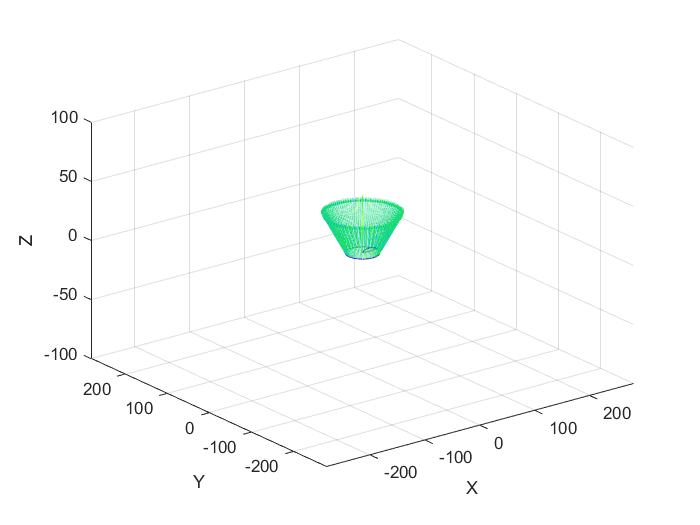

Elapsed time is 9.455720 seconds.


Elapsed time is 10.392492 seconds.


Elapsed time is 11.145749 seconds.


Elapsed time is 11.888341 seconds.


Elapsed time is 12.680797 seconds.


Elapsed time is 13.450622 seconds.


Elapsed time is 14.103945 seconds.


Elapsed time is 14.844798 seconds.


Elapsed time is 15.535982 seconds.


Elapsed time is 16.205936 seconds.


Elapsed time is 16.973773 seconds.


Elapsed time is 17.729920 seconds.


Elapsed time is 18.486864 seconds.


Elapsed time is 19.141875 seconds.


Elapsed time is 19.853621 seconds.


Elapsed time is 20.534577 seconds.


Elapsed time is 21.242058 seconds.


Elapsed time is 21.896289 seconds.


Elapsed time is 22.553054 seconds.


Elapsed time is 23.304601 seconds.


Elapsed time is 24.039793 seconds.


Elapsed time is 24.777034 seconds.


Elapsed time is 25.467394 seconds.


Elapsed time is 26.185385 seconds.


Elapsed time is 26.841727 seconds.


Elapsed time is 27.544292 seconds.


Elapsed time is 28.286207 seconds.


Elapsed time is 29.024288 seconds.


Elapsed time is 29.743127 seconds.


Elapsed time is 30.624788 seconds.


Elapsed time is 31.417125 seconds.


Elapsed time is 32.140428 seconds.


Elapsed time is 32.811283 seconds.


Elapsed time is 33.542989 seconds.


Elapsed time is 34.241855 seconds.


Elapsed time is 34.897964 seconds.


Elapsed time is 35.610942 seconds.


Elapsed time is 36.341783 seconds.


Elapsed time is 37.081199 seconds.


Elapsed time is 37.836547 seconds.


Elapsed time is 38.601603 seconds.


Elapsed time is 39.298301 seconds.


Elapsed time is 39.993592 seconds.


Elapsed time is 40.664862 seconds.


Elapsed time is 41.416178 seconds.


Elapsed time is 42.210886 seconds.


Elapsed time is 42.997590 seconds.


Elapsed time is 43.839556 seconds.


Elapsed time is 44.636241 seconds.


Elapsed time is 45.433335 seconds.


Elapsed time is 46.255641 seconds.


Elapsed time is 46.974634 seconds.


Elapsed time is 47.721875 seconds.


Elapsed time is 48.456092 seconds.


Elapsed time is 49.163981 seconds.


Elapsed time is 49.904955 seconds.


Elapsed time is 50.606127 seconds.


Elapsed time is 51.347587 seconds.


Elapsed time is 52.127060 seconds.


Elapsed time is 53.019007 seconds.


Elapsed time is 53.740864 seconds.


Elapsed time is 54.466429 seconds.


Elapsed time is 55.173860 seconds.


Elapsed time is 55.908084 seconds.


Elapsed time is 56.575628 seconds.


Elapsed time is 57.319528 seconds.


Elapsed time is 58.032585 seconds.


Elapsed time is 58.802084 seconds.


Elapsed time is 59.529351 seconds.


Elapsed time is 60.209603 seconds.


Elapsed time is 60.894377 seconds.


Elapsed time is 61.568726 seconds.


Elapsed time is 62.286977 seconds.


Elapsed time is 62.987350 seconds.


Elapsed time is 63.739680 seconds.


Elapsed time is 64.387210 seconds.


Elapsed time is 65.148374 seconds.


Elapsed time is 65.945078 seconds.


Elapsed time is 67.029108 seconds.


Elapsed time is 68.435798 seconds.


Elapsed time is 69.222579 seconds.


Elapsed time is 70.063022 seconds.


Elapsed time is 70.989417 seconds.


Elapsed time is 71.972800 seconds.


Elapsed time is 72.836109 seconds.


Elapsed time is 73.634549 seconds.


Elapsed time is 74.344190 seconds.


Elapsed time is 75.130766 seconds.


Elapsed time is 75.838434 seconds.


Elapsed time is 76.597478 seconds.


Elapsed time is 77.338884 seconds.


Elapsed time is 78.108507 seconds.


Elapsed time is 78.874036 seconds.


Elapsed time is 79.662983 seconds.


Elapsed time is 80.449311 seconds.


Elapsed time is 81.178487 seconds.


Elapsed time is 81.901485 seconds.


Elapsed time is 82.699877 seconds.


Elapsed time is 83.453053 seconds.


Elapsed time is 84.193760 seconds.


Elapsed time is 84.879731 seconds.


rotx = @(radians) [1,0,0;
                   0,cos(radians),-sin(radians);
                   0,sin(radians),cos(radians)];
               
roty = @(radians) [cos(radians),0,sin(radians);
                   0,1,0;
                   -sin(radians),0,cos(radians)];
               
rotz = @(radians) [cos(radians), -sin(radians), 0;
                   sin(radians), cos(radians),0;
                   0,0,1];
d2r = @(degree) degree*pi/180;
% make AC axis example 1
segments = 100;
starting_vec = [25,0,0].';
starting_rot = eye(3,3);
seg_deg = 360/segments;
pos_seg = zeros([3,segments]);
rot_seg = zeros([3,3,segments]);
axis_vec = [-280,280,-280,280,-100,100];
figure;
tic;
file = fopen('tests\AC_example1.txt','w');
for i=1:segments+1
    rot = rotz(d2r((i-1)*seg_deg));
    pos_seg(:,i) = rot*starting_vec;
    rot_seg(1:3,1:3,i) = rot*rotz(d2r(90))*rotx(d2r(45))*starting_rot;
    cur_pose = [pos_seg(:,i);rot_seg(1:3,3,i)];
    if i==1
        prev_pose = [0,0,0,0,0,1];
        prev_rot = eye(3,3);
    else
        prev_pose = [pos_seg(:,i-1);rot_seg(1:3,3,i-1)];
        prev_rot = rot_seg(:,:,i-1);
    end
    [joint_params] = Inv_kin(cur_pose.',rot_seg(:,:,i),prev_pose,prev_rot);
    txt = joint_params;
    txt(4) = 180*txt(4)/pi;
    txt(5) = 180*txt(5)/pi;
    fprintf(file,'G1 X%0.4f Y%0.4f Z%0.4f A%0.4f C%0.4f\n',txt);
    offset = prev_pose(1:3);
    [O,Q] = forKinPlot(joint_params,offset,cur_pose,prev_pose,prev_rot,axis_vec,50,51);
    hold on;
    toc;
end


fclose('all');

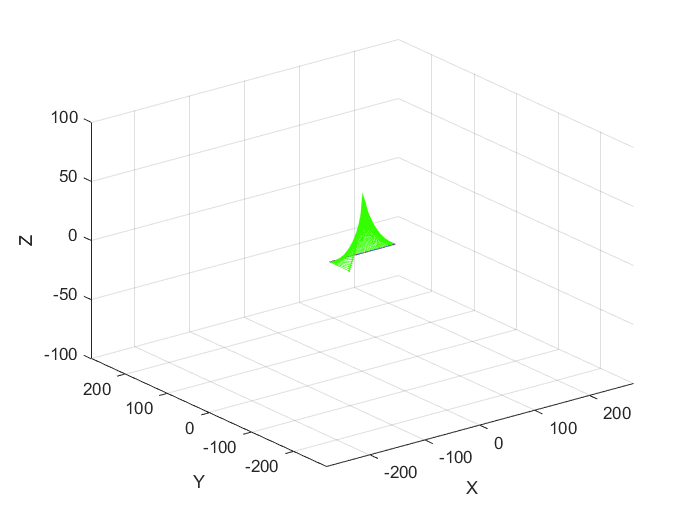

Elapsed time is 0.915647 seconds.


Elapsed time is 1.700015 seconds.


Elapsed time is 2.463815 seconds.


Elapsed time is 3.181867 seconds.


Elapsed time is 3.877003 seconds.


Elapsed time is 4.626465 seconds.


Elapsed time is 5.301644 seconds.


Elapsed time is 6.009307 seconds.


Elapsed time is 6.811205 seconds.


Elapsed time is 7.520066 seconds.


Elapsed time is 8.358631 seconds.


Elapsed time is 9.097357 seconds.


Elapsed time is 9.832903 seconds.


Elapsed time is 10.520597 seconds.


Elapsed time is 11.237303 seconds.


Elapsed time is 11.898098 seconds.


Elapsed time is 12.611390 seconds.


Elapsed time is 13.288565 seconds.


Elapsed time is 14.070084 seconds.


Elapsed time is 14.824071 seconds.


Elapsed time is 15.596332 seconds.


Elapsed time is 16.420716 seconds.


Elapsed time is 17.209070 seconds.


Elapsed time is 17.930002 seconds.


Elapsed time is 18.703288 seconds.


Elapsed time is 19.365546 seconds.


Elapsed time is 20.183547 seconds.


Elapsed time is 20.925852 seconds.


Elapsed time is 21.619307 seconds.


Elapsed time is 22.310725 seconds.


Elapsed time is 23.015917 seconds.


Elapsed time is 23.785626 seconds.


Elapsed time is 24.461391 seconds.


Elapsed time is 25.215307 seconds.


Elapsed time is 25.890572 seconds.


Elapsed time is 26.605210 seconds.


Elapsed time is 27.294790 seconds.


Elapsed time is 28.012385 seconds.


Elapsed time is 28.785691 seconds.


Elapsed time is 29.516506 seconds.


Elapsed time is 30.340631 seconds.


Elapsed time is 31.078782 seconds.


Elapsed time is 31.760456 seconds.


Elapsed time is 32.434297 seconds.


Elapsed time is 33.138377 seconds.


Elapsed time is 33.786694 seconds.


Elapsed time is 34.509975 seconds.


Elapsed time is 35.252259 seconds.


Elapsed time is 36.003330 seconds.


Elapsed time is 36.712157 seconds.


Elapsed time is 37.473098 seconds.


Elapsed time is 38.164339 seconds.


Elapsed time is 38.910495 seconds.


Elapsed time is 39.604838 seconds.


Elapsed time is 40.313736 seconds.


Elapsed time is 41.054683 seconds.


Elapsed time is 41.749230 seconds.


Elapsed time is 42.544384 seconds.


Elapsed time is 43.255344 seconds.


Elapsed time is 43.957203 seconds.


Elapsed time is 44.636371 seconds.


Elapsed time is 45.359308 seconds.


Elapsed time is 46.070365 seconds.


Elapsed time is 46.784219 seconds.


Elapsed time is 47.430521 seconds.


Elapsed time is 48.098844 seconds.


Elapsed time is 48.918740 seconds.


Elapsed time is 49.650280 seconds.


Elapsed time is 50.421481 seconds.


Elapsed time is 51.119155 seconds.


Elapsed time is 51.845276 seconds.


Elapsed time is 52.544364 seconds.


Elapsed time is 53.264924 seconds.


Elapsed time is 54.013453 seconds.


Elapsed time is 54.749185 seconds.


Elapsed time is 55.456404 seconds.


Elapsed time is 56.158866 seconds.


Elapsed time is 56.865406 seconds.


Elapsed time is 57.571668 seconds.


Elapsed time is 58.311786 seconds.


Elapsed time is 59.011524 seconds.


Elapsed time is 59.817864 seconds.


Elapsed time is 60.578581 seconds.


Elapsed time is 61.507384 seconds.


Elapsed time is 62.266256 seconds.


Elapsed time is 63.176293 seconds.


Elapsed time is 64.026129 seconds.


Elapsed time is 64.906970 seconds.


Elapsed time is 65.772261 seconds.


Elapsed time is 66.586054 seconds.


Elapsed time is 67.523565 seconds.


Elapsed time is 68.289366 seconds.


Elapsed time is 69.090399 seconds.


Elapsed time is 69.903396 seconds.


Elapsed time is 70.679916 seconds.


Elapsed time is 71.424096 seconds.


Elapsed time is 72.254854 seconds.


Elapsed time is 73.013652 seconds.


Elapsed time is 73.813518 seconds.


Elapsed time is 74.632518 seconds.


Elapsed time is 75.412033 seconds.


%example 2
rotx = @(radians) [1,0,0;
                   0,cos(radians),-sin(radians);
                   0,sin(radians),cos(radians)];
               
roty = @(radians) [cos(radians),0,sin(radians);
                   0,1,0;
                   -sin(radians),0,cos(radians)];
               
rotz = @(radians) [cos(radians), -sin(radians), 0;
                   sin(radians), cos(radians),0;
                   0,0,1];
d2r = @(degree) degree*pi/180;
% make AC axis example 1
segments = 100;
starting_vec = [-60,0,0].';
ending_vec = [60,0,0].';
starting_rot = rotx(d2r(90));
seg_deg = 180/segments;
seg_pos = 120/segments;
pos_seg = zeros([3,segments]);
rot_seg = zeros([3,3,segments]);
axis_vec = [-280,280,-280,280,-100,100];
figure;
tic;
file = fopen('tests\AC_example2.txt','w');
for i=1:segments+1
    pos_seg(:,i) = starting_vec + [(i-1)*seg_pos;0;0];
    rot = rotx(-d2r((i-1)*seg_deg));
    rot_seg(1:3,1:3,i) = rot*starting_rot;
    cur_pose = [pos_seg(:,i);rot_seg(1:3,3,i)];
    if i==1
        prev_pose = [0,0,0,0,0,1];
        prev_rot = eye(3,3);
    else
        prev_pose = [pos_seg(:,i-1);rot_seg(1:3,3,i-1)];
        prev_rot = rot_seg(:,:,i-1);
    end
    [joint_params] = Inv_kin(cur_pose.',rot_seg(:,:,i),prev_pose,prev_rot);
    txt = joint_params;
    txt(4) = 180*txt(4)/pi;
    txt(5) = 180*txt(5)/pi;
    fprintf(file,'G1 X%0.4f Y%0.4f Z%0.4f A%0.4f C%0.4f\n',txt);
    offset = prev_pose(1:3);
    [O,Q] = forKinPlot(joint_params,offset,cur_pose,prev_pose,prev_rot,axis_vec,50,51);
    hold on;
    toc;
end


fclose('all');